% roomDimensions = [4 4 2.5];
% receiverCoord = [2 1 1.8];
% sourceCoord = [3 1 1.8];
% h = figure;
% plotRoom(roomDimensions,receiverCoord,sourceCoord,h)
%
% %Image source
% imageSource = [-sourceCoord(1) -sourceCoord(2) -sourceCoord(3)];
% plot3(imageSource(1),imageSource(2),imageSource(3),"gx",LineWidth=2)
% plot3([imageSource(1) receiverCoord(1)], ...
%       [imageSource(2) receiverCoord(2)], ...
%       [imageSource(3) receiverCoord(3)],Color="k",LineWidth=2)
%
%
% view([17.55 45.07])

% plot3([1 2 3],[4 5 6],[7 8 9; 10 11 12])

% t = 0:pi/50:10*pi;
% st = sin(t);
% ct = cos(t);
% plot3(st,ct,t)

h2 = figure;
roomDimensions = [4 3 3];
receiverCoord = [2 1.5 1.8];
sourceCoord = [3 1 2];

plotStyles = {'ro', 'gs', 'bd', 'c^', 'm+', 'y*', 'k.', 'rx'};

result(2,:)

ans =      5     1     2


[gradient , yc]=lineFuntion(receiverCoord,result(2,:))

gradient = -0.1667

yc = 1.8333

yint=findY(gradient,yc,4)

yint = 1.1667


plotRoom(roomDimensions,receiverCoord,sourceCoord,h2)
result=plot1stOrdImgSrc(roomDimensions,sourceCoord)

result =     -3     1     2
     5     1     2
     3     1     4
     3     1    -2
     3     5     2
     3    -1     2


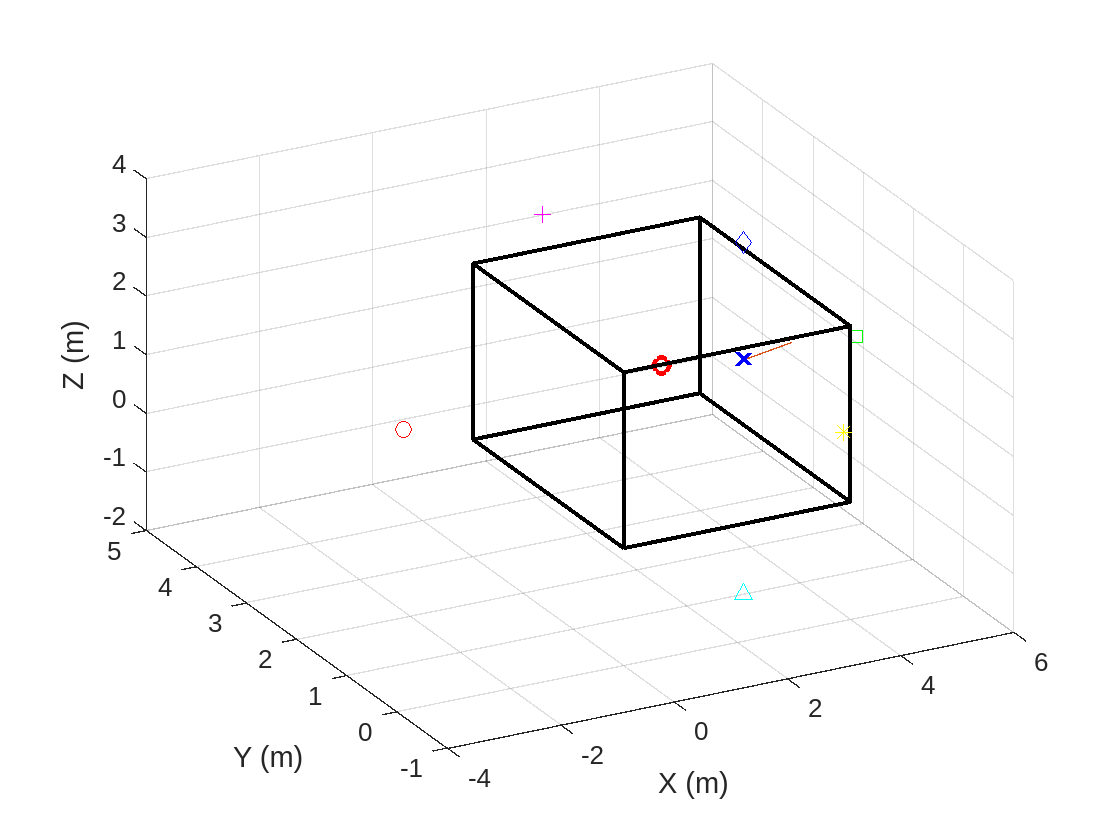

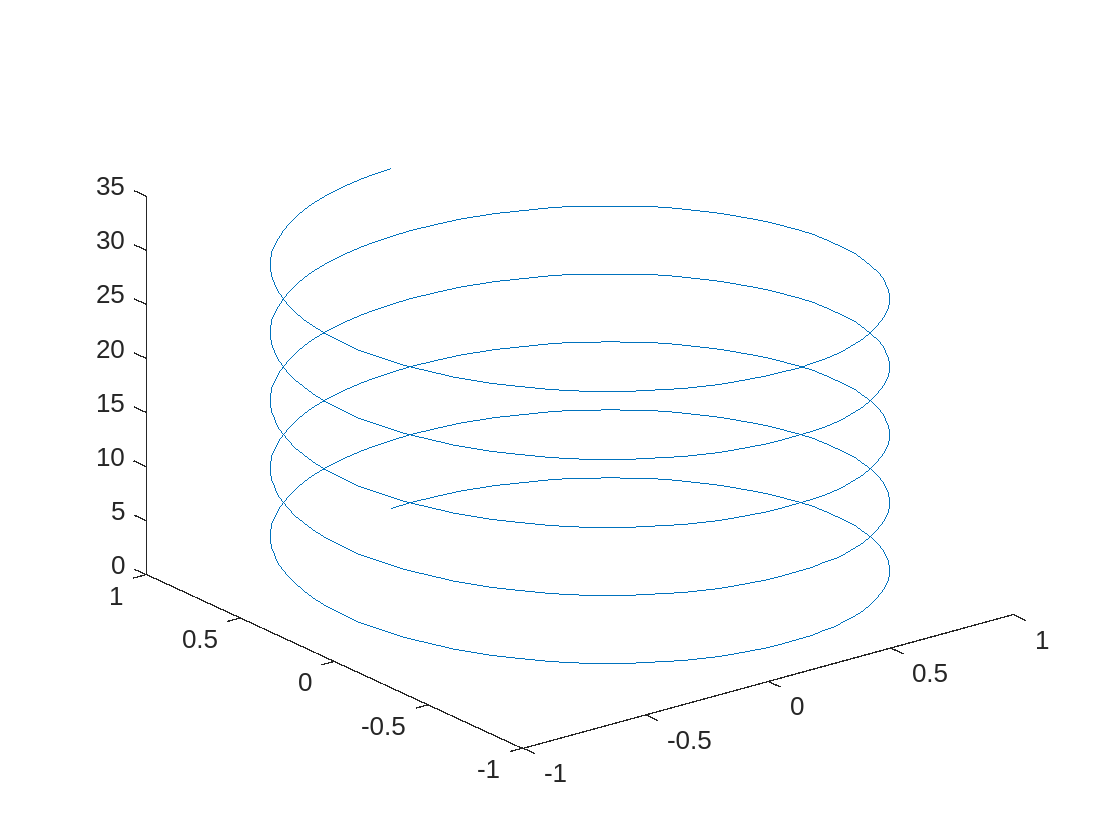

hold on
px =[sourceCoord(1),4];
py=[sourceCoord(2),yint ];
pz =[sourceCoord(3),sourceCoord(3)];
plot3(px,py,pz)
for kk=1:6
    isourceCoord=result(kk,:);
    plot3(isourceCoord(1),isourceCoord(2),isourceCoord(3),plotStyles{kk})
end
hold off

% h2 = figure;
% roomDimensions = [4 6 2.5];
% receiverCoord = [2 2 1];
% sourceCoord = [3 1 1.8];
% 
% plotRoom(roomDimensions,receiverCoord,sourceCoord,h2)
% 
% Lx = roomDimensions(1);
% Ly = roomDimensions(2);
% Lz = roomDimensions(3);
% 
% xlim([-3*Lx,3*Lx]);
% ylim([-3*Ly,3*Ly]);
% zlim([-3*Lz,3*Lz]);
% 
% 
% x = sourceCoord(1);
% y = sourceCoord(2);
% z = sourceCoord(3);
% sourceXYZ = plot1stOrdImgSrc(roomDimensions,sourceCoord)'
% 
% 
% %Restricting the Number of Simulated Images
% FVect = [125 250 500 1000 2000 4000];
% % In A[] rows are odd 6 walls and the columns represnt freq dependednt
% % coeffcients
% 
% A = [0.10 0.20 0.40 0.60 0.50 0.60;...
%     0.10 0.20 0.40 0.60 0.50 0.60;...
%     0.10 0.20 0.40 0.60 0.50 0.60;...
%     0.10 0.20 0.40 0.60 0.50 0.60;...
%     0.02 0.03 0.03 0.03 0.04 0.07;...
%     0.02 0.03 0.03 0.03 0.04 0.07].';
% B =[0.8;...
%     0.80;...
%     0.90;...
%     0.70;...
%     0.86;...
%     0.95].';
% 
% %Estimate RT60
% V = Lx*Ly*Lz;
% WallXZ = Lx*Lz;
% WallYZ = Ly*Lz;
% WallXY = Lx*Ly;
% 
% S = WallYZ*(B(:,1)+B(:,2))+WallXZ.*(B(:,3)+B(:,4))+WallXY.*(B(:,5)+B(:,6));
% 
% c  = 343; % Speed of sound (m/s)
% RT60 = (55.25/c)*V./S
% %% Deduce the maximum impulse response length (in samples) based on the largest value in RT60. Assume a sample rate of 48 kHz.
% fs = 48000;
% impResLength = fix(max(RT60)*fs)
% impResRange=c*(1/fs)*impResLength
% nMax = min(ceil(impResRange./(2.*Lx)),10);
% lMax = min(ceil(impResRange./(2.*Ly)),10);
% mMax = min(ceil(impResRange./(2.*Lz)),10);
% 
% 
% % Increase the range to plot more images
% %USE HERE THE VALS nMAX IF NEEDED ; TAKES ALONG TIME THO:::
% % v = nma;
% % nVect = -nMax:nMax;
% % lVect = -lMax:lMax;
% % mVect = -mMax:mMax;
% v = 1;
% nVect = -v:v;
% lVect = -v:v;
% mVect = -v:v;
% 
% 
% 
% % plotColors = {'red*', 'green*', 'blue*', 'cyan*', 'magenta*', 'yellow*', 'black*', 'magenta*'};
% % Array of MATLAB plot colors with symbols
% plotStyles = {'ro', 'gs', 'bd', 'c^', 'm+', 'rx'};
% 
% 
% for n = nVect
%     for l = lVect
%         for m = mVect
%             xyz = [n*2*Lx; l*2*Ly; m*2*Lz];
%             isourceCoords = xyz - sourceXYZ;
%             for kk=1:6
%                 isourceCoord=isourceCoords(:,kk);
%                 plot3(isourceCoord(1),isourceCoord(2),isourceCoord(3),plotStyles{kk})
%             end
%         end
%     end
% end

% %% Initialize an empty matrix
% resultMatrix = [];
% 
% % Number of iterations
% numIterations = 5;
% 
% % Example for loop
% for i = 1:numIterations
%     % Generate a row to append
%     newRow = rand(1, 3);  % Adjust the size as needed
% 
%     % Append the row to the result matrix
%     resultMatrix = [resultMatrix; newRow];
% end
% 
% % Display the result matrix
% disp('Result Matrix:');
% disp(resultMatrix);
% 


% roomDimensions = [10, 5];  % Room dimensions (width, height)
% sourceCoord = [2, 2];      % Source coordinates (x, y)
% receiverCoord = [8, 3];    % Receiver coordinates (x, y)
%
% plotImageSourcesAndRays(roomDimensions, sourceCoord, receiverCoord);
